# JoyStick Demo - Gator Summer 2022

### REV A

Joystick Demo to drive the Gator via a usb connected joystick to the main system

%%% Path Declaration
addpath(...
    "ACT\",...
    "GPSCOORDS\",...
    "SENSE\",...
    "SETUP\",...
    "SHUTDOWN\",...
    "THINK\")
disp("FOLDER PATHS ADDED")

FOLDER PATHS ADDED


%%$ Variable Decleration
controlFlag = 1;                                   % Start Control counter
% sampleTime = 0.0001;                                  % Sample time [s]
% t = 0:sampleTime:100;                              % Time array
% r = rateControl(1/sampleTime);                     % reset control loop  rate
% reset(r);                                          % reset loop time to zero
wayStep=1;

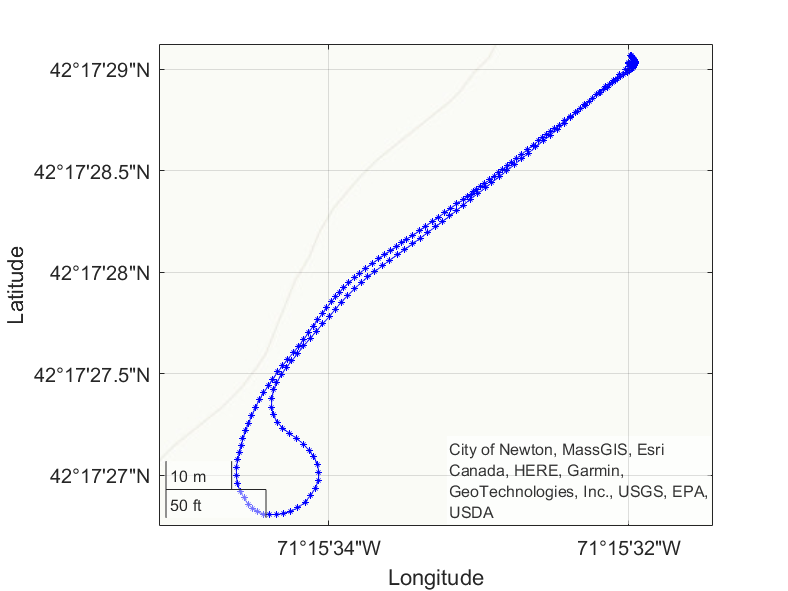

ggaData = 266×1 struct array with fields:
    TalkerID
    MessageID
    FixStatus
    Latitude
    Longitude
    GroundSpeed
    TrueCourseAngle
    UTCDateTime
    MagneticVariation
    ModeIndicator
    NavigationStatus
    Status


%%% SETUP 
hold off
format long
[lat1,lon1,utc1]=PlotGPSlog("C:\Users\Skull\Documents\GatorTemp\RTK_GPS\GPS_Right_Data.ubx");

ggaData = 293×1 struct array with fields:
    TalkerID
    MessageID
    FixStatus
    Latitude
    Longitude
    GroundSpeed
    TrueCourseAngle
    UTCDateTime
    MagneticVariation
    ModeIndicator
    NavigationStatus
    Status


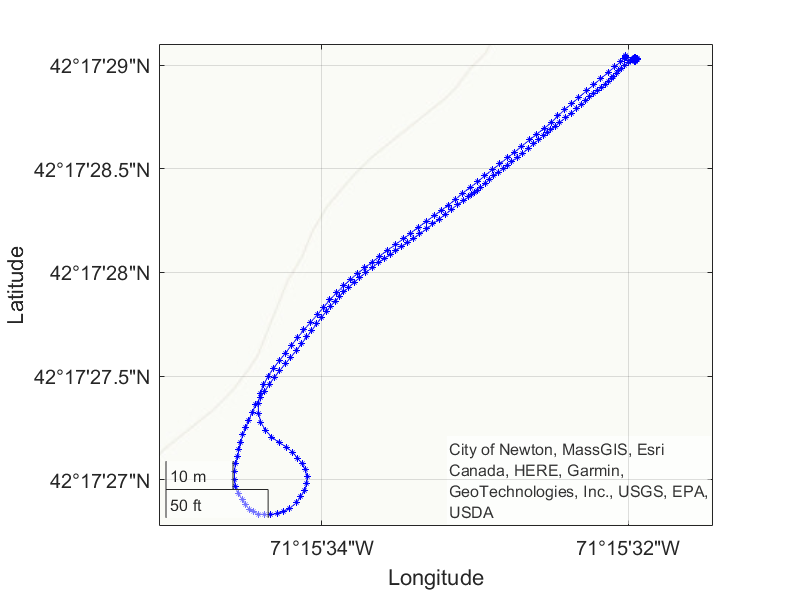

[lat2,lon2,utc2]=PlotGPSlog("C:\Users\Skull\Documents\GatorTemp\RTK_GPS\GPS_Left_Data.ubx");

size(lat1)

ans =      1   266


size(lat2)

ans =      1   293


size(utc1)

ans =      1   266


size(utc2)

ans =      1   293


count=1;
for i=1:size(utc1,2)
    for j=1:size(utc2,2)
        if utc2(j)==utc1(i)
            lat1new(1,count)=lat1(1,i);
            lon1new(1,count)=lon1(1,i);
            lat2new(1,count)=lat2(1,j);
            lon2new(1,count)=lon2(1,j);
            count=count+1;
            break
        end
    end
end

clf
middlelat=mean([lat1new; lat2new]);
middlelon=mean([lon1new; lon2new]);
waypoints=[middlelat;middlelon]

waypoints =   42.291402583333337  42.291402666666670  42.291402666666670  42.291402666666670  42.291402583333337  42.291402500000004  42.291402333333338  42.291402250000004  42.291402083333338  42.291401833333339  42.291401666666665  42.291401666666665  42.291401583333332  42.291401583333339  42.291401583333339  42.291401750000006  42.291401750000006  42.291401666666673  42.291401499999999  42.291401416666666  42.291401333333333  42.291401250000000  42.291401166666667  42.291401000000000  42.291400916666667  42.291400750000001  42.291400583333328  42.291400416666661  42.291400249999995  42.291399833333330  42.291399583333330  42.291399249999998  42.291398999999998  42.291398749999999  42.291398500000000  42.291398416666667  42.291398333333333  42.291398166666667  42.291398000000001  42.291397833333335  42.291397833333335  42.291397750000002  42.291397666666668  42.291397666666668  42.291397583333335  42.291397583333335  42.291397583333335  42.291397583333335  42.291397666666668  42.291

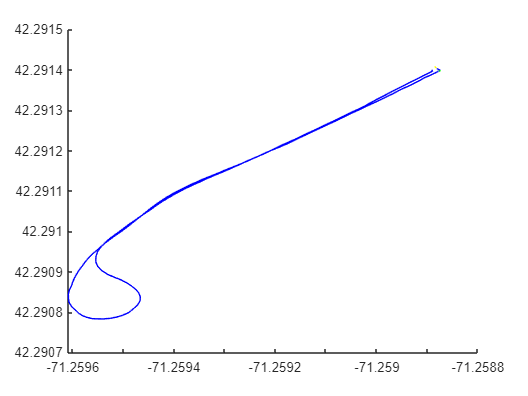

figure(2)
hold on
plot(middlelon,middlelat,'-b');
 plot(lon1new(1:20),lat1new(1:20),'-y');
 plot(lon2new(1:20),lat2new(1:20),'-g');
hold off


objects = setupGPSDemo('COM11');

%%% MAIN
while (controlFlag > 0)           % loop for number of elements in t
    senseobjects=sense(objects);

    [motorControls, wayStep]=thinkPathB2C(senseobjects, waypoints, wayStep)

    actGPS(objects.mega, motorControls)
    controlFlag = controlFlag+1;         % increment loops

    if wayStep>size(waypoints,2)
        motorControls.throttle=-1;
        actGPS(objects.mega, motorControls)
        break
    end
end 

%%% SHUTDOWN
clear